# Computing Derivatives in IFDIFF (of the Canonical Example)

Having correct state and parameters sensitivities, i.e. the derivative of the trajectory w.r.t. changes in the initial values or parameters, is cruicial for derivative-based optimization. By restricting the maximum integrator step size to 0.1, also the naive approach is capable of reproducing the forward trajectory. However, the sensitivities generated by the naive approach are completely useless.

### Compute Sensitivities

As before, we first need to compute the solution function of the ODE.

initPaths();
integrator = @ode45;
odeoptionsrhs_test = odeset( 'AbsTol', 1e-14,'RelTol', 1e-12);
datahandle = prepareDatahandleForIntegration('canonicalExampleRHS', 'integrator', func2str(integrator), 'options', odeoptionsrhs_test);

tspan         = [0 20];
initialvalues = [1;0];
parameters    = 5.437;
sol           = solveODE(datahandle, tspan, initialvalues, parameters); 

This can then be used to compute the so called **sensitivities**. These are the derivatives of the solution in the direction of the initial values and or the paremeters. Currently `IFDIFF` supports 3 different methods of sensitivitie generation of first order. They can be categorized into: 

- external numerical differentiation (flags `END_full`, `END_piecewise`) and the 

- the variational differential equations (flag `VDE`)

The methods are the following:

- Usually, method `VDE` delivers best results in terms of accuracy, as it calculates error-controlled sensitivities. It uses the variational differential equations on each interval and performes updates at the switching points to ensure accurate sensitivities at the precalculated forward solution. However, the occuring augmented differential system might be large size and thus slow to compute. Required state derivatives of the right hand side are approximated using automated finite differencing.

- The method `END_piecewise` computes the interval sensitivities using external numerical differentiation (finite differencing) and connects these using the same updates as used in the VDE method. This requires multiple evaluations of interval solutions, but might be faster on larger systems.

- When using `END_full`, external numerical differention is used on multiple full horizon solutions. The individual trajectories are calculated with switching point detection. Thus, no updates between switches are required. In general, this approach is less accurate and slower than `END_piecewise`, but might be the a good choice for highly instable ODEs.

% Data for finite differences
dim_y = size(sol.y, 1);
dim_p = length(parameters);
FDstep = generateFDstep(dim_y, dim_p, 'hy_rel_flag', true,'hp_rel_flag', true, 'hy_min', 1e-6, 'hp_min', 1e-6);

integrator_options = odeset( 'AbsTol', 1e-14,'RelTol', 1e-12);
sensitivities_function_ENDfull = generateSensitivityFunction(datahandle, sol, FDstep, 'method', 'END_full', 'calcGy', true,'calcGp',true, 'Gmatrices_intermediate', true, 'save_intermediates', true);
sensitivities_function_ENDpiece = generateSensitivityFunction(datahandle, sol, FDstep, 'method', 'END_piecewise', 'calcGy', true,'calcGp',true, 'Gmatrices_intermediate', true, 'save_intermediates', false);
sensitivities_function_VDE = generateSensitivityFunction(datahandle, sol, FDstep, 'integrator_options', integrator_options, 'method', 'VDE', 'calcGy', true,'calcGp',false, 'Gmatrices_intermediate', true, 'save_intermediates', false);

The results for different times are returned as struct arrays. as can be ssen here:

t = [20, 15, 11.25, 11.26, 3, 3, 0, 20];

sensitivities_full = sensitivities_function_ENDfull(t);
sensitivities_piece = sensitivities_function_ENDpiece(t);
sensitivities_VDE = sensitivities_function_VDE(t); disp(sensitivities_VDE);

  1×8 struct array with fields:

    t
    Gy
    Gy_intermediate
    Uy
    Gp
    Gp_intermediate
    Up



### Plot Sensitivities

The full step derivative computation isn't very accurate, so we plot the results of the other two methods:

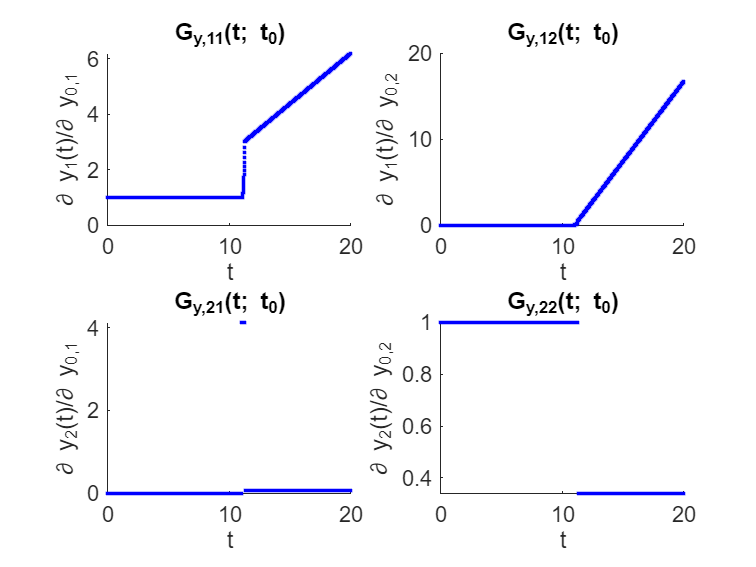

sensitivities_function_ENDpiecewise = generateSensitivityFunction(datahandle, sol, FDstep, 'method', 'END_piecewise', 'Gy', true,'Gp',false, 'Gmatrices_intermediate', true, 'save_intermediates', true);
sensitivities_function_VDE = generateSensitivityFunction(datahandle, sol, FDstep, 'method', 'VDE', 'calcGy', true,'calcGp',false, 'Gmatrices_intermediate', true, 'save_intermediates', true);

t_plot = 0:0.01:20;
sensitivities_END_plot = sensitivities_function_VDE(t_plot);
sensitivities_END_plot2 = sensitivities_function_ENDpiecewise(t_plot);

CanonicalSensPlot(t_plot, sensitivities_END_plot, 1)

CanonicalSensPlot(t_plot, sensitivities_END_plot2, 2)

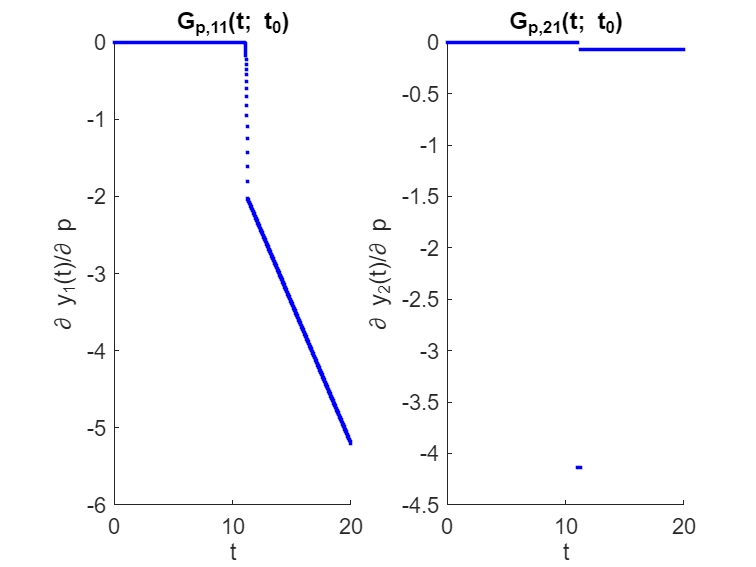


%% Plot sensitivities parameters

%sensitivities_function_ENDpiecewise = generateSensitivityFunction(datahandle, sol, FDstep, 'method', 'END_piecewise', 'Gy', false,'Gp',true, 'Gmatrices_intermediate', true, 'save_intermediates', true);
sensitivities_function_VDE = generateSensitivityFunction(datahandle, sol, FDstep, 'method', 'VDE', 'calcGy', false,'calcGp',true, 'Gmatrices_intermediate', true, 'save_intermediates', true);

t_plot = 0:0.01:20;
%sensitivities_END_plot = sensitivities_function_ENDpiecewise(t_plot);
sensitivities_END_plot = sensitivities_function_VDE(t_plot);

figure(3)
sensall5 = arrayfun(@(x) x.Gp(1,1), sensitivities_END_plot);
subplot(1,2,1)
plot(t_plot,sensall5, '.b')
xlabel('t');
ylabel('\partial y_1(t)/\partial p')
title('G_{p,11}(t; t_0)')
set(gca, 'FontSize', 12);
set(gca, 'Box', 'off');

sensall6 = arrayfun(@(x) x.Gp(2,1), sensitivities_END_plot);
subplot(1,2,2)
plot(t_plot,sensall6, '.b')
xlabel('t');
ylabel('\partial y_2(t)/\partial p')
title('G_{p,21}(t; t_0)')
set(gca, 'FontSize', 12);
set(gca, 'Box', 'off');